%% lidar_plot_offline.m  ---------------------------------------------
% 저장한 한 프레임(csv) 불러와서 폴라 스캔 재현

% ---------- 1. 파일 읽기 ----------
fileName = 'dataset/lidar/lidar_000320.csv';   % ← 경로/이름 수정
rangeMat = readmatrix(fileName);

% ---------- 2. 센서 파라미터 (Webots 설정과 동일해야 함) ----------
hRes = size(rangeMat,2);          % 수평 해상도
nLayer = size(rangeMat,1);        % 수직 레이어 수
fov   = deg2rad(60);              % 수평 FoV [rad]  ← 예: 60°
maxR  = 8.0;                      % 최대 거리 [m]   ← world 파일과 일치
circleR=3.0;
% ---------- 3. 가운데 레이어 하나 선택 ----------
rValues  = rangeMat( ceil(nLayer/2), : );

% ---------- 4. 극 → 직교 변환 ----------
thetaVec = linspace( fov/2 , -fov/2 , hRes );  % +왼 → −오른
xEnd = -rValues .* sin(thetaVec);
yEnd =  rValues .* cos(thetaVec);

% ---------- 5. 유효 히트 필터 (빈 빔 제거) ----------
tol   = 6;%0.05;                               % 5 cm 여유
isHit = (rValues < maxR - tol) & ~isinf(rValues) & ~isnan(rValues);

% ---------- 6. 그림 ----------
figure('Name','Offline LiDAR Polar Scan','NumberTitle','off');
ax = axes; hold(ax,'on'); axis(ax,'equal'); grid(ax,'on');
xlabel('X [m]'); ylabel('Y [m]'); title('LiDAR Polar Scan (offline)');

% (a) 모든 빔 파란 선
for k = 1:hRes
    line(ax,[0 xEnd(k)],[0 yEnd(k)],'Color',[0 0.6 1 0.5]);  % 0.5=알파
end

% (b) 히트 점 빨간 scatter
scatter(ax,xEnd(isHit),yEnd(isHit),25,'filled','r');


%% -------- 7. DBSCAN 군집화 · 객체별 거리 계산 -----------------
% ▶ 7-1) (x,y) 히트 좌표 배열
xyHits = [xEnd(isHit).' , yEnd(isHit).'];      % [N×2]

% ▶ 7-2) DBSCAN 실행  (eps·minPts는 장면 규모에 따라 조정)
eps    = 0.15;    % 한 클러스터 내 최대 점-간 거리 [m]
minPts = 4;       % 최소 점 개수(노이즈 제거용)
clabel = dbscan(xyHits, eps, minPts);          % 벡터 길이 = N

% ▶ 7-3) 노이즈(라벨 −1) 제거
valid  = clabel > 0;
xyC    = xyHits(valid,:);    cID = clabel(valid);

% ▶ 7-4) 클러스터별 특성치
uID  = unique(cID);                  % 실제 객체ID 목록
nObj = numel(uID);                   % 검출된 물체 개수
objCentroid = zeros(nObj,2);         % (x,y) 중심
objDist     = zeros(nObj,1);         % 원점(로봇)까지 거리

for i = 1:nObj
    idx = (cID == uID(i));
    objCentroid(i,:) = mean(xyC(idx,:),1);         % 산술평균
    objDist(i)       = hypot(objCentroid(i,1), ...
                             objCentroid(i,2));    % √(x²+y²)
end

% ▶ 7-5) 시각화 : 각 클러스터 다른 색 + 중심 '×'
cmap = lines(max(uID));     % 색상 팔레트
for i = 1:nObj
    idx = (cID == uID(i));
    scatter(ax, xyC(idx,1), xyC(idx,2), 30, ...
            'filled', 'MarkerFaceColor', cmap(uID(i),:));
    plot(ax, objCentroid(i,1), objCentroid(i,2), ...
         'kx', 'MarkerSize',10,'LineWidth',2);
    text(objCentroid(i,1), objCentroid(i,2), ...
        sprintf('  %.2fm',objDist(i)) , ...
        'Color',cmap(uID(i),:),'FontWeight','bold');
end
title(ax, sprintf('LiDAR Scan – %d objects', nObj));

fprintf('Detected %d objects\n', nObj);

Detected 2 objects


disp(table((1:nObj).', objCentroid, objDist, ...
     'VariableNames',{'ID','Centroid_xy','Range_m'}));

    ID        Centroid_xy         Range_m
    __    ____________________    _______

    1     -0.36482     0.71247    0.80044
    2      0.52096      1.3897     1.4842



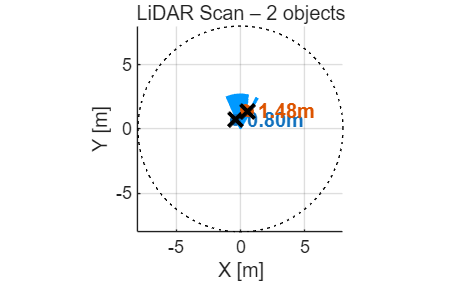


t = linspace(0,2*pi,360);
plot(ax,maxR*cos(t),maxR*sin(t),'k:');
xlim(ax,[-maxR maxR]); ylim(ax,[-maxR maxR]);

% 1) 원하는 좌표 지정 (행, 열)
% obs = [8 13;
%        14 7;];

nc=20

nc = 20

nl=26

nl = 26

obs_tmp=objCentroid.*10

obs_tmp =    -3.6482    7.1247
    5.2096   13.8974


obs_tmp(:,2)=obs_tmp(:,2)

obs_tmp =    -3.6482    7.1247
    5.2096   13.8974


obs_tmp(:,1)=obs_tmp(:,1)+10;%nc/2
obs=ceil(obs_tmp)

obs =      7     8
    16    14


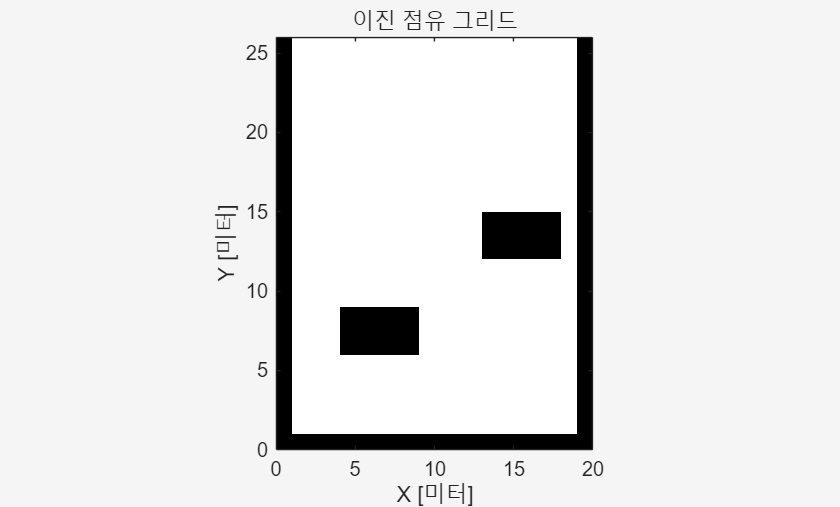


obsRow = nl - obs(:,2) + 1;   % y  → row (위·아래 뒤집기)
obsCol = obs(:,1);            % x  → col
obsRC  = [obsRow obsCol];     % [row col]  형태

binMap   = createBinaryMap(nl,nc,obsRC,[3,4]);


fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(binMap),"Parent",ax);

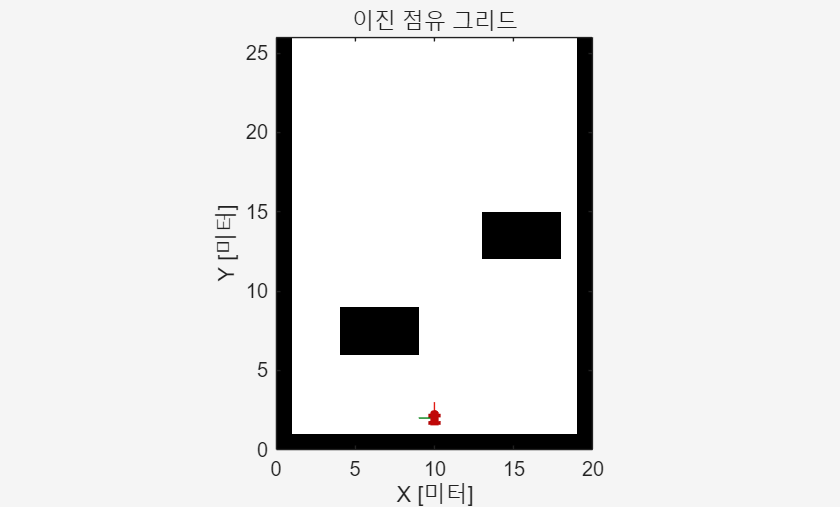


mapMatrix = binMap;
mapScale = 1;

scanAngles = -3*pi/8:pi/8:3*pi/8;
maxRange = 12;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

% Max speed parameters
maxLinSpeed = 0.3;
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 10;
initY = 2;
initTheta = pi/2;

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

mdl = "AOMR_reward_goal";
Tfinal = 100;
sampleTime = 0.1;

agentBlk = mdl + "/Agent";

open_system(mdl)
open_system(mdl + "/Environment")
obsInfo = rlNumericSpec([numel(scanAngles) 1],...
    "LowerLimit",zeros(numel(scanAngles),1),...
    "UpperLimit",ones(numel(scanAngles),1)*maxRange);
numObservations = obsInfo.Dimension(1);
numActions = 2;
actInfo = rlNumericSpec([numActions 1],...
    "LowerLimit",-1,...
    "UpperLimit",1);
env = rlSimulinkEnv(mdl,agentBlk,obsInfo,actInfo);
env.ResetFcn = @(in)exampleHelperRLAvoidObstaclesResetFcn(in,scanAngles,maxRange,mapMatrix);
env.UseFastRestart = "Off";

## DDPG Agent

statePath = [
    featureInputLayer(numObservations, "Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","CriticStateFC1")
    reluLayer("Name","CriticRelu1")
    fullyConnectedLayer(25,"Name","CriticStateFC2")];
actionPath = [
    featureInputLayer(numActions,"Normalization","none","Name","Action")
    fullyConnectedLayer(25,"Name","CriticActionFC1")];
commonPath = [
    additionLayer(2,"Name","add")
    reluLayer("Name","CriticCommonRelu")
    fullyConnectedLayer(1,"Name","CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"CriticStateFC2","add/in1");
criticNetwork = connectLayers(criticNetwork,"CriticActionFC1","add/in2");
criticNetwork = dlnetwork(criticNetwork);
criticOptions = rlOptimizerOptions("LearnRate",1e-3,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,"ObservationInputNames","State","ActionInputNames","Action");
actorNetwork = [
    featureInputLayer(numObservations,"Normalization","none","Name","State")
    fullyConnectedLayer(50,"Name","actorFC1")
    reluLayer("Name","actorReLU1")
    fullyConnectedLayer(50, "Name","actorFC2")
    reluLayer("Name","actorReLU2")
    fullyConnectedLayer(2, "Name","actorFC3")
    tanhLayer("Name","Action")];
actorNetwork = dlnetwork(actorNetwork);

actorOptions = rlOptimizerOptions("LearnRate",1e-4,"L2RegularizationFactor",1e-4,"GradientThreshold",1);
actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

### Create DDPG agent object

Specify the agent options.

agentOpts = rlDDPGAgentOptions(...
    "SampleTime",sampleTime,...
    "ActorOptimizerOptions",actorOptions,...
    "CriticOptimizerOptions",criticOptions,...
    "DiscountFactor",0.995, ...
    "MiniBatchSize",128, ...
    "ExperienceBufferLength",1e6); 

agentOpts.NoiseOptions.Variance = 0.1;
agentOpts.NoiseOptions.VarianceDecayRate = 1e-5;
obstacleAvoidanceAgent = rlDDPGAgent(actor,critic,agentOpts);
open_system(mdl + "/Agent")

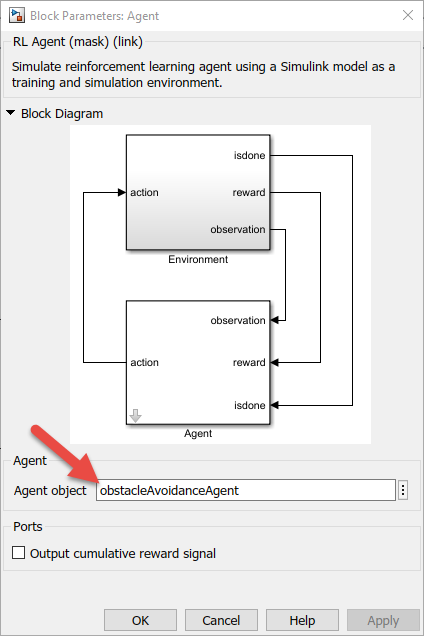

maxEpisodes = 10000;
maxSteps = ceil(Tfinal/sampleTime);
trainOpts = rlTrainingOptions(...
    "MaxEpisodes",maxEpisodes, ...
    "MaxStepsPerEpisode",maxSteps, ...
    "ScoreAveragingWindowLength",50, ...
    "StopTrainingCriteria","AverageReward", ...
    "StopTrainingValue",400, ...
    "Verbose", true, ...
    "Plots","training-progress");

doTraining = true;%true; % Toggle this to true for training. 

if doTraining
    % Train the agent.
    trainingStats = train(obstacleAvoidanceAgent,env,trainOpts);
else
    load("trainedObstacleAvoidanceAgent1.mat", "obstacleAvoidanceAgent");
end

에피소드:   1/10000 | 에피소드 보상:    39.97 | 에피소드 스텝:  464 | 평균 보상:    39.97 | 스텝 수:  464 | 에피소드 Q0:    -0.03
에피소드:   2/10000 | 에피소드 보상:    66.65 | 에피소드 스텝:  607 | 평균 보상:    53.31 | 스텝 수: 1071 | 에피소드 Q0:     0.13
에피소드:   3/10000 | 에피소드 보상:   859.31 | 에피소드 스텝: 1000 | 평균 보상:   321.98 | 스텝 수: 2071 | 에피소드 Q0:     0.84
에피소드:   4/10000 | 에피소드 보상:   185.74 | 에피소드 스텝:  636 | 평균 보상:   287.92 | 스텝 수: 2707 | 에피소드 Q0:     1.70
에피소드:   5/10000 | 에피소드 보상:    47.61 | 에피소드 스텝:  434 | 평균 보상:   239.86 | 스텝 수: 3141 | 에피소드 Q0:     0.37
에피소드:   6/10000 | 에피소드 보상:    95.83 | 에피소드 스텝:  472 | 평균 보상:   215.85 | 스텝 수: 3613 | 에피소드 Q0:     0.45
에피소드:   7/10000 | 에피소드 보상:  1033.63 | 에피소드 스텝: 1000 | 평균 보상:   332.68 | 스텝 수: 4613 | 에피소드 Q0:     2.51
에피소드:   8/10000 | 에피소드 보상:   113.75 | 에피소드 스텝:  710 | 평균 보상:   305.31 | 스텝 수: 5323 | 에피소드 Q0:     0.53
에피소드:   9/10000 | 에피소드 보상:    92.70 | 에피소드 스텝:  219 | 평균 보상:   281.69 | 스텝 수: 5542 | 에피소드 Q0:     2.73
에피소드:  10/10000 | 에피소드 보상:     6.01 | 에피소드 스텝:   43 | 평균 보상:   254.12 | 스

다음 사용 중 오류가 발생함: rl.internal.train.OffPolicyTrainer/run_internal_/nestedRunEpisode (304번 라인)
시뮬레이션이 중단됨

오류 발생: rl.internal.train.OffPolicyTrainer/run_internal_ (371번 라인)
                            out = nestedRunEpisode(policy);
            

## Simulate

% save("trainedObstacleAvoidanceAgent_250626_2.mat", "obstacleAvoidanceAgent");

% 1. 에이전트 로드
% load("trainedObstacleAvoidanceAgent1.mat", "obstacleAvoidanceAgent");
load("trainedObstacleAvoidanceAgent_250625.mat", "obstacleAvoidanceAgent");

% 2. 모델 열기
mdl = "AOMR_reward_goal";
open_system(mdl);

% 3. Simulink 모델에 에이전트 연결
%    "Agent"라는 이름의 block이 Simulink 안에 있어야 함
%    이 block은 RL Agent 블록이어야 하며,
%    파라미터 "Agent"에 obstacleAvoidanceAgent를 연결
rlAgentBlock = mdl + "/Agent";
set_param(rlAgentBlock, "Agent", "obstacleAvoidanceAgent");

% 4. 시뮬레이션 시간 설정
set_param(mdl, "StopTime", "200");

% 5. 시뮬레이션 실행
out = sim(mdl);

## Visualize

To visualize the simulation of the robot driving around the environment with range sensor readings, use the helper, `exampleHelperAvoidObstaclesPosePlot`.

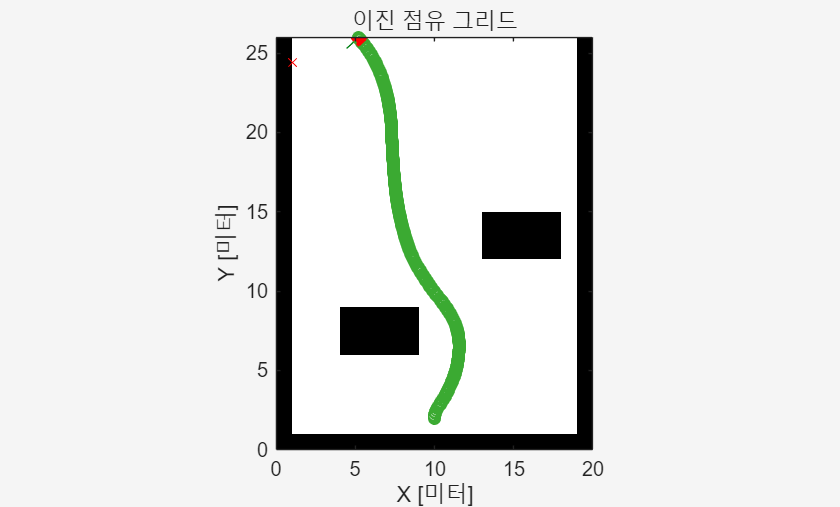

for i = 1:5:size(out.range,3)
    u = out.pose(i,:);
    r = out.range(:,:,i);
    
    AvoidObstaclesPosePlot(u,mapMatrix,mapScale,r,scanAngles,ax);
    % hold on;
    scatter(ax,out.pose(1:i,1), out.pose(1:i,2))
    drawnow;
end

% 1) 원하는 좌표 지정 (행, 열)
% obs = [8 13;
%        14 7;];

nc=20

nc = 20

nl=26

nl = 26

% obsRC = [11, 8; 19, 13]
% obsRC = [11, 15; 19, 9]
obsRC = [6, 15; 13, 9; 20, 14]

obsRC =      6    15
    13     9
    20    14


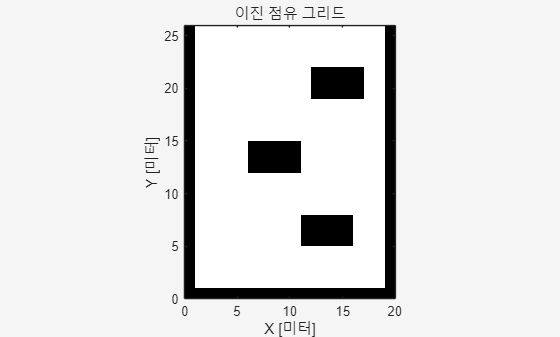



binMap   = createBinaryMap(nl,nc,obsRC,[3,4]);


fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(binMap),"Parent",ax);

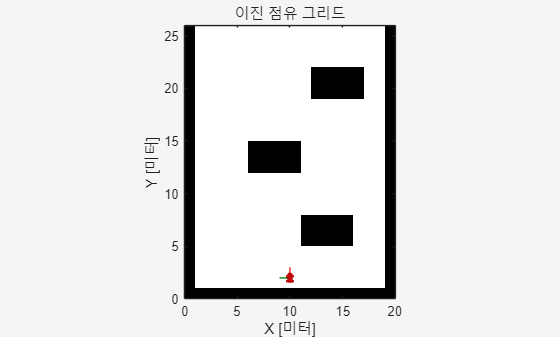


mapMatrix = binMap;
mapScale = 1;

scanAngles = -3*pi/8:pi/8:3*pi/8;
maxRange = 12;
lidarNoiseVariance = 0.1^2;
lidarNoiseSeeds = randi(intmax,size(scanAngles));

% Max speed parameters
maxLinSpeed = 0.3;
maxAngSpeed = 0.3;

% Initial pose of the robot
initX = 10;
initY = 2;
initTheta = pi/2;

fig = figure("Name","simpleMap");
set(fig, "Visible","on");
ax = axes(fig);

show(binaryOccupancyMap(mapMatrix),"Parent",ax);
hold on
plotTransforms([initX,initY,0],eul2quat([initTheta,0,0]),"MeshFilePath","groundvehicle.stl","View","2D");
light;
hold off

function binMap = createBinaryMap(nRows,nCols,obsRC,obsSizeRC)


M = size(obsRC,1);

% ---- obsSizeRC 규격 정규화 → M×2 행렬 [h v] ----
if isscalar(obsSizeRC)               % S           → S×S
    obsSizeRC = repmat([obsSizeRC obsSizeRC],M,1);
elseif isvector(obsSizeRC) && numel(obsSizeRC)==1
    obsSizeRC = repmat([obsSizeRC obsSizeRC],M,1);
elseif isvector(obsSizeRC) && numel(obsSizeRC)==2
    obsSizeRC = repmat(obsSizeRC(:).',M,1);   % 1×2 → M×2
elseif isequal(size(obsSizeRC),[M 1])
    obsSizeRC = [obsSizeRC obsSizeRC];        % M×1 → M×2(S,S)
else
    assert(isequal(size(obsSizeRC),[M 2]), ...
        "obsSizeRC must be scalar, M×1, 1×2, or M×2.");
end

% ---- 맵 초기화 ----
binMap          = false(nRows,nCols);
binMap(:,1)     = true;    % 왼쪽 벽
binMap(nRows,:) = true;    % 아래 벽
binMap(:,nCols) = true;    % 오른쪽 벽
% binMap(1,:)   = true;    % ← 위쪽도 막으려면 주석 해제

% ---- 장애물 삽입 ----
for k = 1:M
    r0 = obsRC(k,1);  c0 = obsRC(k,2);
    hv = obsSizeRC(k,2);   vv = obsSizeRC(k,1);  % h=가로, v=세로
    hr = floor(hv/2);      vr = floor(vv/2);     % 반경

    rIdx = max(r0-vr,1)      :  min(r0+vr, nRows);
    cIdx = max(c0-hr,1)      :  min(c0+hr, nCols);
    binMap(rIdx,cIdx) = true;
end
end